% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

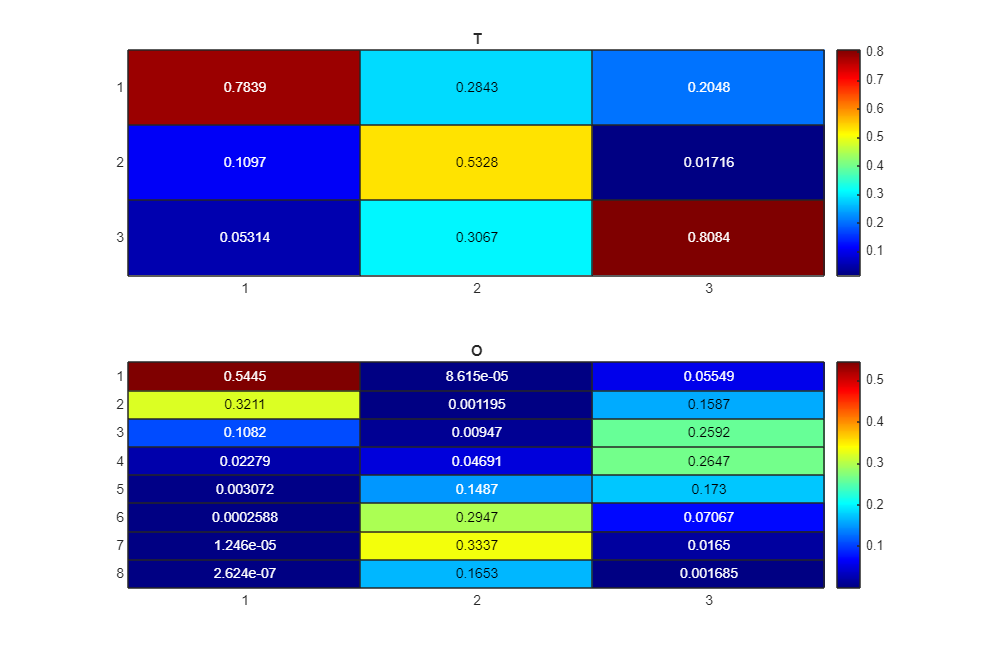

k = 3;
d = 8;

lam = 3;

T = lam * eye(k) + abs(randn(k, k));
T = diag(sum(T, 1)) \ T ;

O = zeros(d, k);

for i = 1:k
    O(:, i) = binopdf(1:d, d, rand);
end
O = Stochasticize(O);


if(rank(T) ~= k || rank(O) ~= k)
error("Insuffucient rank: Rank of T: " + rank(T) + " - and Rank of O: " + rank(O) + " - must be at least: " + k);
end

% k = 2;
% d = 6;
% 
% T = [.9 .1; .05 .95];
% 
% O = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;...
% 7/12, 1/12, 1/12, 1/12, 1/12, 1/12];

% 
% k = 3;
% d = 10;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;]';

% k = 3;
% d = 8;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     3/15, 3/20, 3/50;]';

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

eig(T)

ans =    0.320663325474520
   0.745792614350596
   1.000000000000000


L = zeros(k, k, d);

for i = 1:size(L, 1)
    for j = 1:size(L, 2)
        for l = 1:size(L, 3)
            L(i,j,l) = T(i,j) * O(l,j);
        end
    end
end


Generate an observational sequence based on the defined HMM

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

U{1} = (O * T);
U{2} = O;
U{3} = (O * T');

P3 = cpdgen(U);

Generate Probability Density Tensors

tic
M = ProbabilityTensorGenerate(seq, 3, d);
toc

Elapsed time is 0.463612 seconds.



ranks = [1, 3, 3, 1];  

core = Core(P3);
tic
[TT, e] = core.mps(ranks);
toc

Elapsed time is 0.004376 seconds.




TT.cores{1}.core

ans = ans(:,:,1) =

  -0.823917761329100  -0.507092123632683  -0.181527715100990  -0.049240650210877  -0.040583154886252  -0.085735439448115  -0.119476534587662  -0.073266277223595


ans(:,:,2) =

   0.142099533420296   0.092131052943440   0.026536338314090  -0.043669138830953  -0.202695258702046  -0.500282787791781  -0.701549904973642  -0.430311417369305


ans(:,:,3) =

  -0.514844562987671   0.621487094228292   0.555185262321993   0.197294250683769   0.034837273850489  -0.005932615903260  -0.014300378071080  -0.008935234945586


TT.cores{2}.core

ans = ans(:,:,1) =

  -0.829285185323964  -0.506530758043867  -0.178961349014650  -0.042075881612739  -0.014807245137347  -0.022805699042303  -0.031271264661435  -0.019164670922675
   0.025436243554134   0.012876945966830   0.002484692486939  -0.006654172836480  -0.028472175659724  -0.069999419784637  -0.098141997648318  -0.060197077426472
  -0.000583068520317   0.000670424596388   0.000605062289635   0.000216099941536   0.000040397370123  -0.000000839027297  -0.000007722835300  -0.000004916291893


ans(:,:,2) =

  -0.119260961788242  -0.079117171777649  -0.027755814713639   0.008542429344516   0.060973112458846   0.152237027800551   0.213579249258066   0.131005975884618
  -0.001517549200390  -0.000422341808316   0.007555897473830   0.049541738204482   0.195021845144897   0.478536422225292   0.670902563428243   0.411509531306235
   0.002026210642083   0.001431655146696   0.000575140003695   0.000147465830736   0.000038780084808   0.000041410701787   0.000055011181273   0.00003366668406

TT.cores{3}.core

ans =    0.325127440194995   0.198724511417382   0.070403024712418   0.017472756012481   0.009532174763136   0.018072135774487   0.025060790761806   0.015365130326136
   0.009155373628238   0.004588250567961   0.000402532475657  -0.005423233041592  -0.022137575902712  -0.054365859543852  -0.076221424607287  -0.046751709477604
  -0.000305328427600   0.000373690130777   0.000332823117345   0.000117751094965   0.000019026522728  -0.000008073085010  -0.000014901656585  -0.000009238310020



e

e =      6.367784617096113e-17
